**I. Amostragem e Reconstrução de Sinais**

**Exercício 02**

**a)**

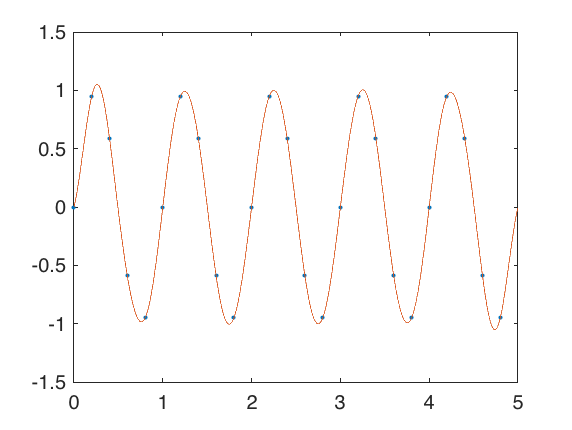

Ta = 0.2;
t = 0:Ta:5-Ta;
x = sin(2*pi*t);

[X,T] = ReconstroiSinal(x,Ta);

plot(t,x, "."); hold on;
plot(T,X); hold off;

O sinal foi reconstruido sem perdas de informação.

**b)**

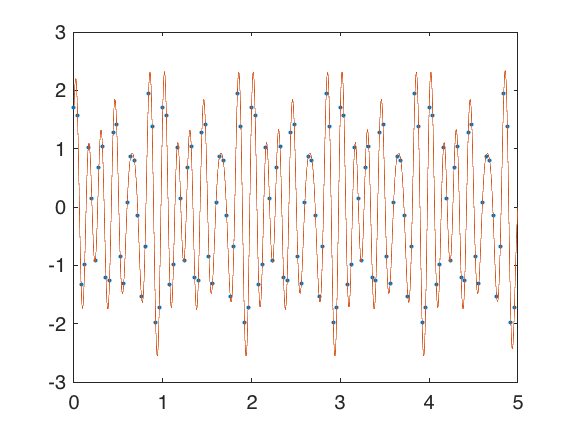

Ta = 0.04;
t = 0:Ta:5-Ta;
y = sin(10*pi*t) + cos(12*pi*t) + cos(14*pi*t - pi/4);

[Y,T] = ReconstroiSinal(y,Ta);

plot(t,y, "."); hold on;
plot(T,Y); hold off;

O sinal foi reconstruido sem perdas de informação.

**c)**

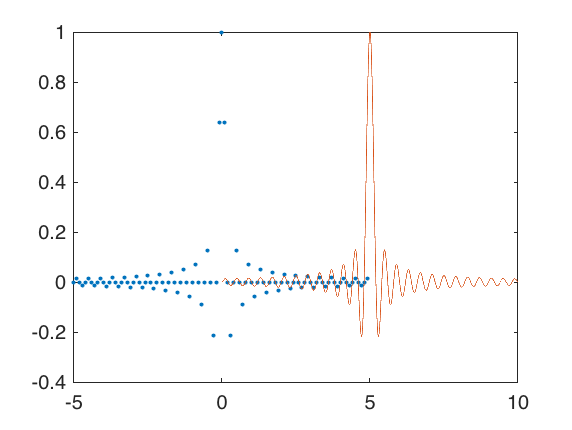

Ta = 0.1;
t = -5:Ta:5-Ta;
z = sinc(5*t);

[Z,T] = ReconstroiSinal(z,Ta);

plot(t,z, "."); hold on;
plot(T,Z); hold off;

O sinal reconstruído começa em t=0 em vez de t=-5. Isto significa que a reconstrução do sinal considera a primeira amostra como sendo tirada no instante t=0.

**Exercício 03**

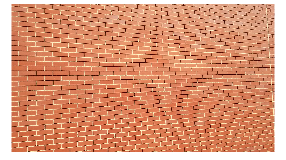

% I = [altura x largura x 3 (RGB)]
% Em cada camada RGB, os píxeis representam o respetivo valor de 0-255.
I = imread("Parede.jpg"); 
imshow(I);

1 píxel por cada 2 píxeis

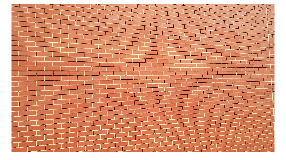

I2 = I(1:2:end,1:2:end,:);
imshow(I2);

1 píxel por cada 4 píxeis

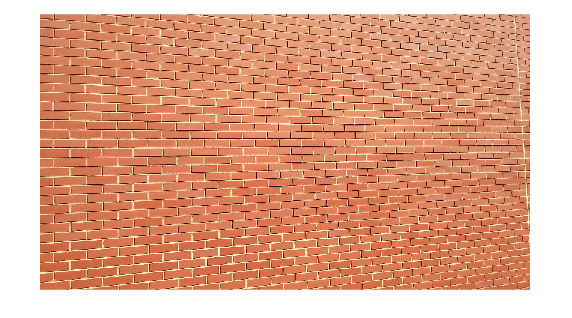

I4 = I(1:4:end,1:4:end,:);
imshow(I4);

1 píxel por cada 8 píxeis

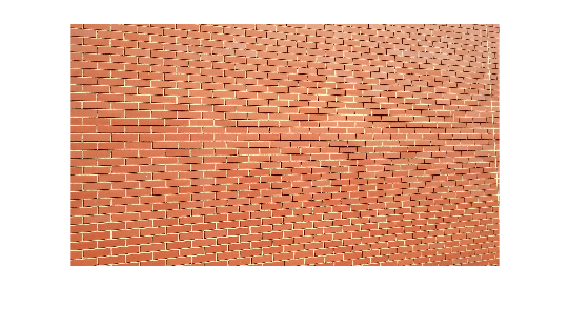

I8 = I(1:8:end,1:8:end,:);
imshow(I8);

1 píxel por cada 16 píxeis

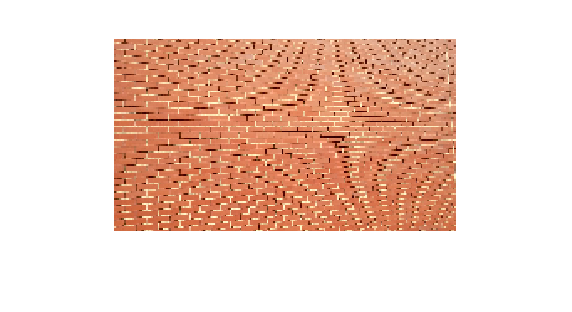

I16 = I(1:16:end,1:16:end,:);
imshow(I16);

**II. Transformada Discreta de Fourier (bidimensional) Aplicada a Imagens**

**Exercício 01**

**a)**

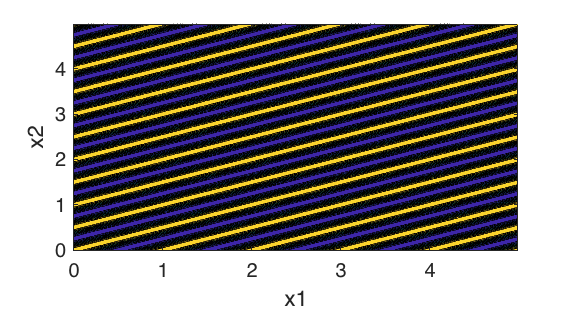

Ta = 0.01;

x1 = 0:Ta:5-Ta;
x2 = x1';

y = cos(2*pi*(x1 - 2*x2));

contourf(x1, x2, y);
xlabel("x1");
ylabel("x2");

**b)**

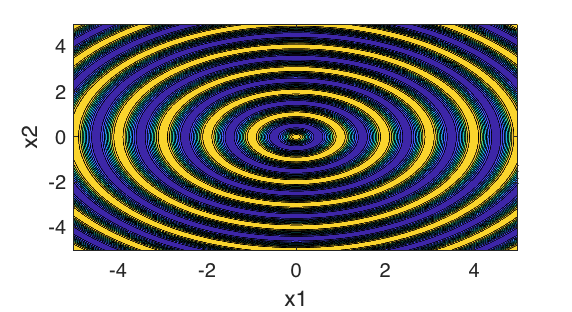

Ta = 0.01;

x1 = -5:Ta:5-Ta;
x2 = x1';

y = cos(2*pi*sqrt(x1.^2 + x2.^2));

contourf(x1, x2, y);
xlabel("x1");
ylabel("x2");